# To overlay high-res image onto low-res image

% Steps:
% 1. Find center of high-res image in low-res image (human input)
% 2. Take snip of low-res image and register to high-res image
% 3. Apply same transformation to full image
% 4. Save each as 8-bit tiff

% 2018-11 MM

## Set up directories

clear
% Folder where images are stored
im_dir= 'R:\viscog\USERS\EMI\HighLowRes_ImageOverlay';

% Low-res and High-res image filenames
filename_low=['Slide3_slice5_R100G500_10Xwholebrain.tif (red)' '.tif'];
filename_high=['Slide3_slice5_R200G400_20X.tif (red)' '.tif'];

% Output filenames
output_filename_low='Slide3_slice5_R100G500_10Xwholebrain_reg-1.tif';
output_filename_high='Slide3_slice5_R200G400_20X_reg-1.tif';

% Resolution of images (e.g. 10x image = 10)
lowsc=10;
highsc=20;

% Amount to scale for registration
regscale=0.5;

## Load tiff images

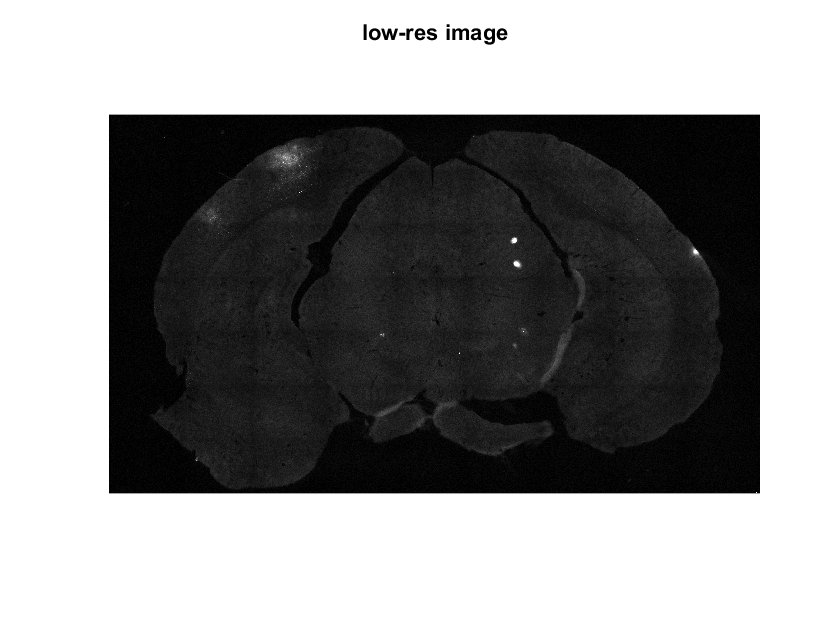

% Load low-res image
    InfoImage.low=imfinfo([im_dir filesep filename_low]);
    im_low=zeros(InfoImage.low.Height,InfoImage.low.Width,length(InfoImage.low),'double');

    TifLink = Tiff([im_dir filesep filename_low], 'r');
    for i=1:length(InfoImage.low)
       TifLink.setDirectory(i);
       im_low(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(98);
    imagesc(im_low)
    colormap gray; 
    axis off; axis equal
    title('low-res image')

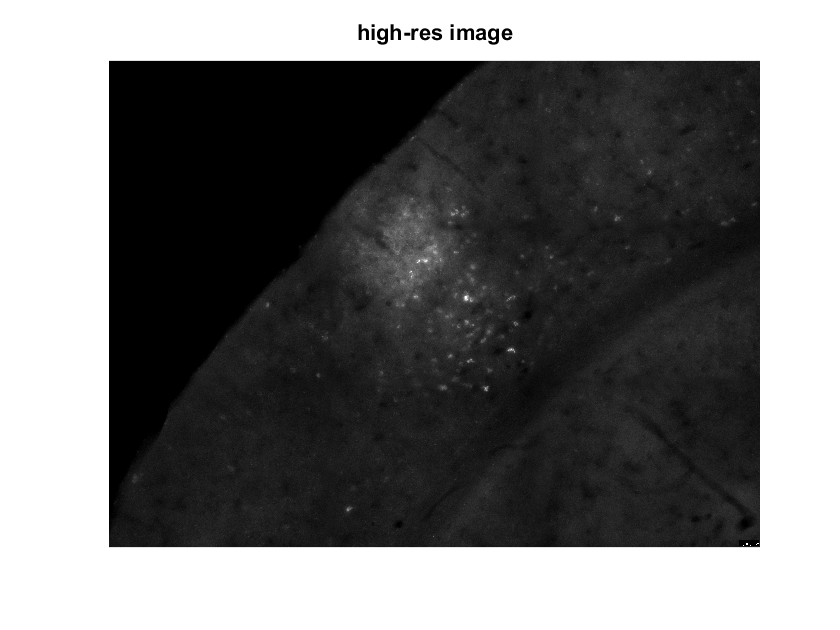


% Load high-res image
    InfoImage.high=imfinfo([im_dir filesep filename_high]);
    im_high=zeros(InfoImage.high.Height,InfoImage.high.Width,length(InfoImage.high),'double');

    TifLink = Tiff([im_dir filesep filename_high], 'r');
    for i=1:length(InfoImage.high)
       TifLink.setDirectory(i);
       im_high(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(99);
    imagesc(im_high)
    colormap gray; 
    axis off; axis equal
    title('high-res image')

## Prepare images for registration

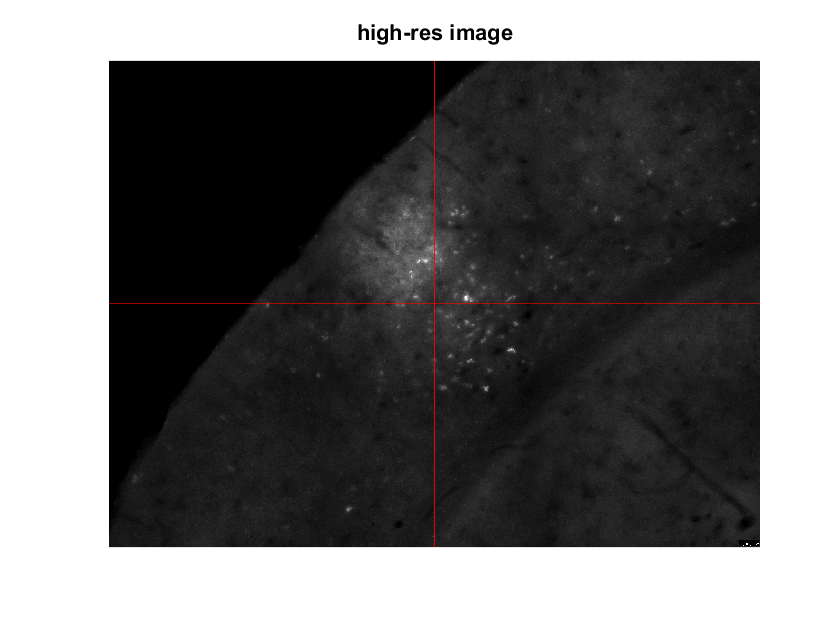

    % Downsample high-res image
    im_high_sc=imresize(im_high, lowsc/highsc);

    figure(99);
    %set(gcf,'position',[4 200 685 467]);
    vx = [round(size(im_high, 2)/2) round(size(im_high, 2)/2)]; vy = [1 size(im_high, 1)];
    hx = [1 size(im_high, 2)]; hy = [round(size(im_high, 1)/2) round(size(im_high, 1)/2)];
    line(hx,hy,'Color','red','LineStyle','-')
    line(vx,vy,'Color','red','LineStyle','-')

## Click on a point for initial centering

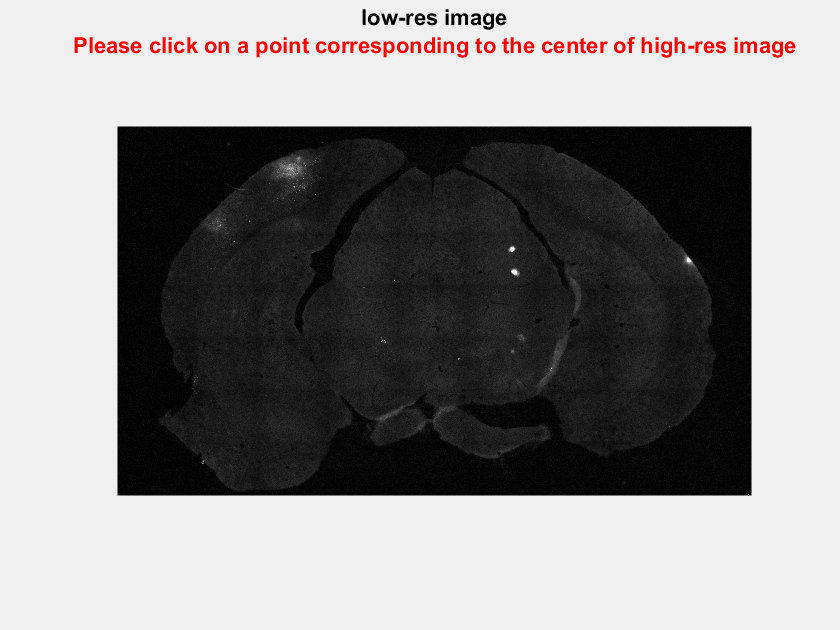

    figure(98);
    %set(gcf,'position',[692 200 685 467]);
    title(['low-res image',{'\color{red}Please click on a point corresponding to the center of high-res image'}])
    [centerH,centerW] = ginput(1);

    
    % Take a snip of the low-res image
    H=size(im_high_sc,1);
    W=size(im_high_sc,2);
    h1=floor(centerH-H/2);
    h2=h1+H-1;
    w1=floor(centerW-W/2);
    w2=w1+W-1;
    
    im_low_snip=im_low(h1:h2,w1:w2);
    
    % Downsample both images sufficiently for registration
    im_low_snip_small=imresize(im_low_snip,regscale);
    im_high_sc_small=imresize(im_high_sc,regscale);
   

## Register the images

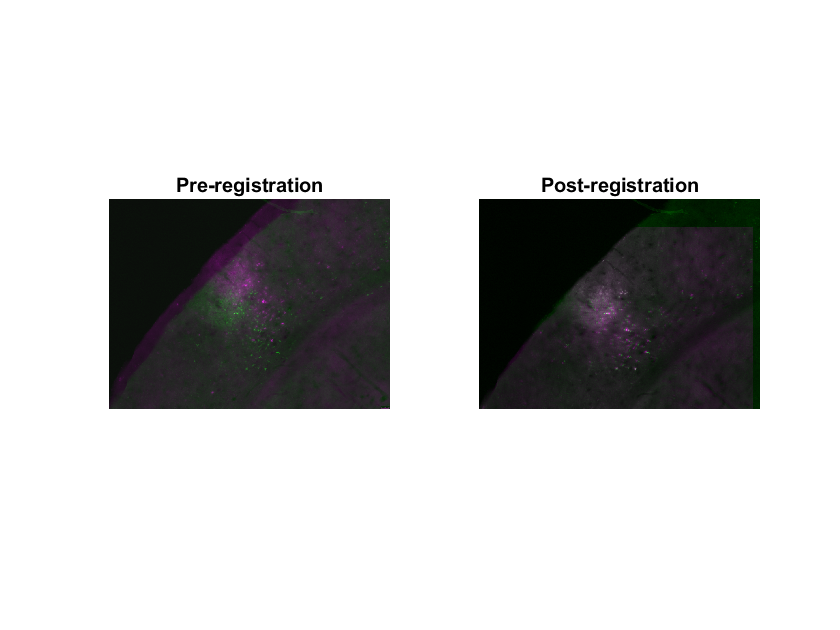

    moving=im_high_sc_small;
    fixed=im_low_snip_small;
    [optimizer, metric] = imregconfig('multimodal');
    
    tform = imregtform(moving, fixed, 'translation', optimizer, metric);
    im_reg = imwarp(moving,tform,'OutputView',imref2d(size(fixed)));
   
    figure;
    subplot(1,2,1)
    imshowpair(im_low_snip_small, im_high_sc_small,'Scaling','joint'); hold on
    title('Pre-registration')
    subplot(1,2,2)
    imshowpair(fixed, im_reg,'Scaling','joint'); hold off
    title('Post-registration')

## Apply the registration onto full image

    centerHcorr=(centerH+tform.T(3,2)/regscale)*highsc/lowsc;
    centerWcorr=(centerW+tform.T(3,1)/regscale)*highsc/lowsc;
    
    H1=size(im_high,1);
    W1=size(im_high,2);
    h3=floor(centerHcorr-H1/2);
    h4=h3+H1-1;
    w3=floor(centerWcorr-W1/2);
    w4=w3+W1-1;
    
    % Upsample low-res image, embed high-res image at original resolution
    im_low_sc=imresize(im_low,highsc/lowsc);
    im_high_embed=zeros(size(im_low_sc,1), size(im_low_sc,2));
    im_high_embed(h3:h4,w3:w4)=im_high;
    
    figure;
    imshowpair(imresize(im_low_sc, 0.5), imresize(im_high_embed, 0.5),'Scaling','joint'); 

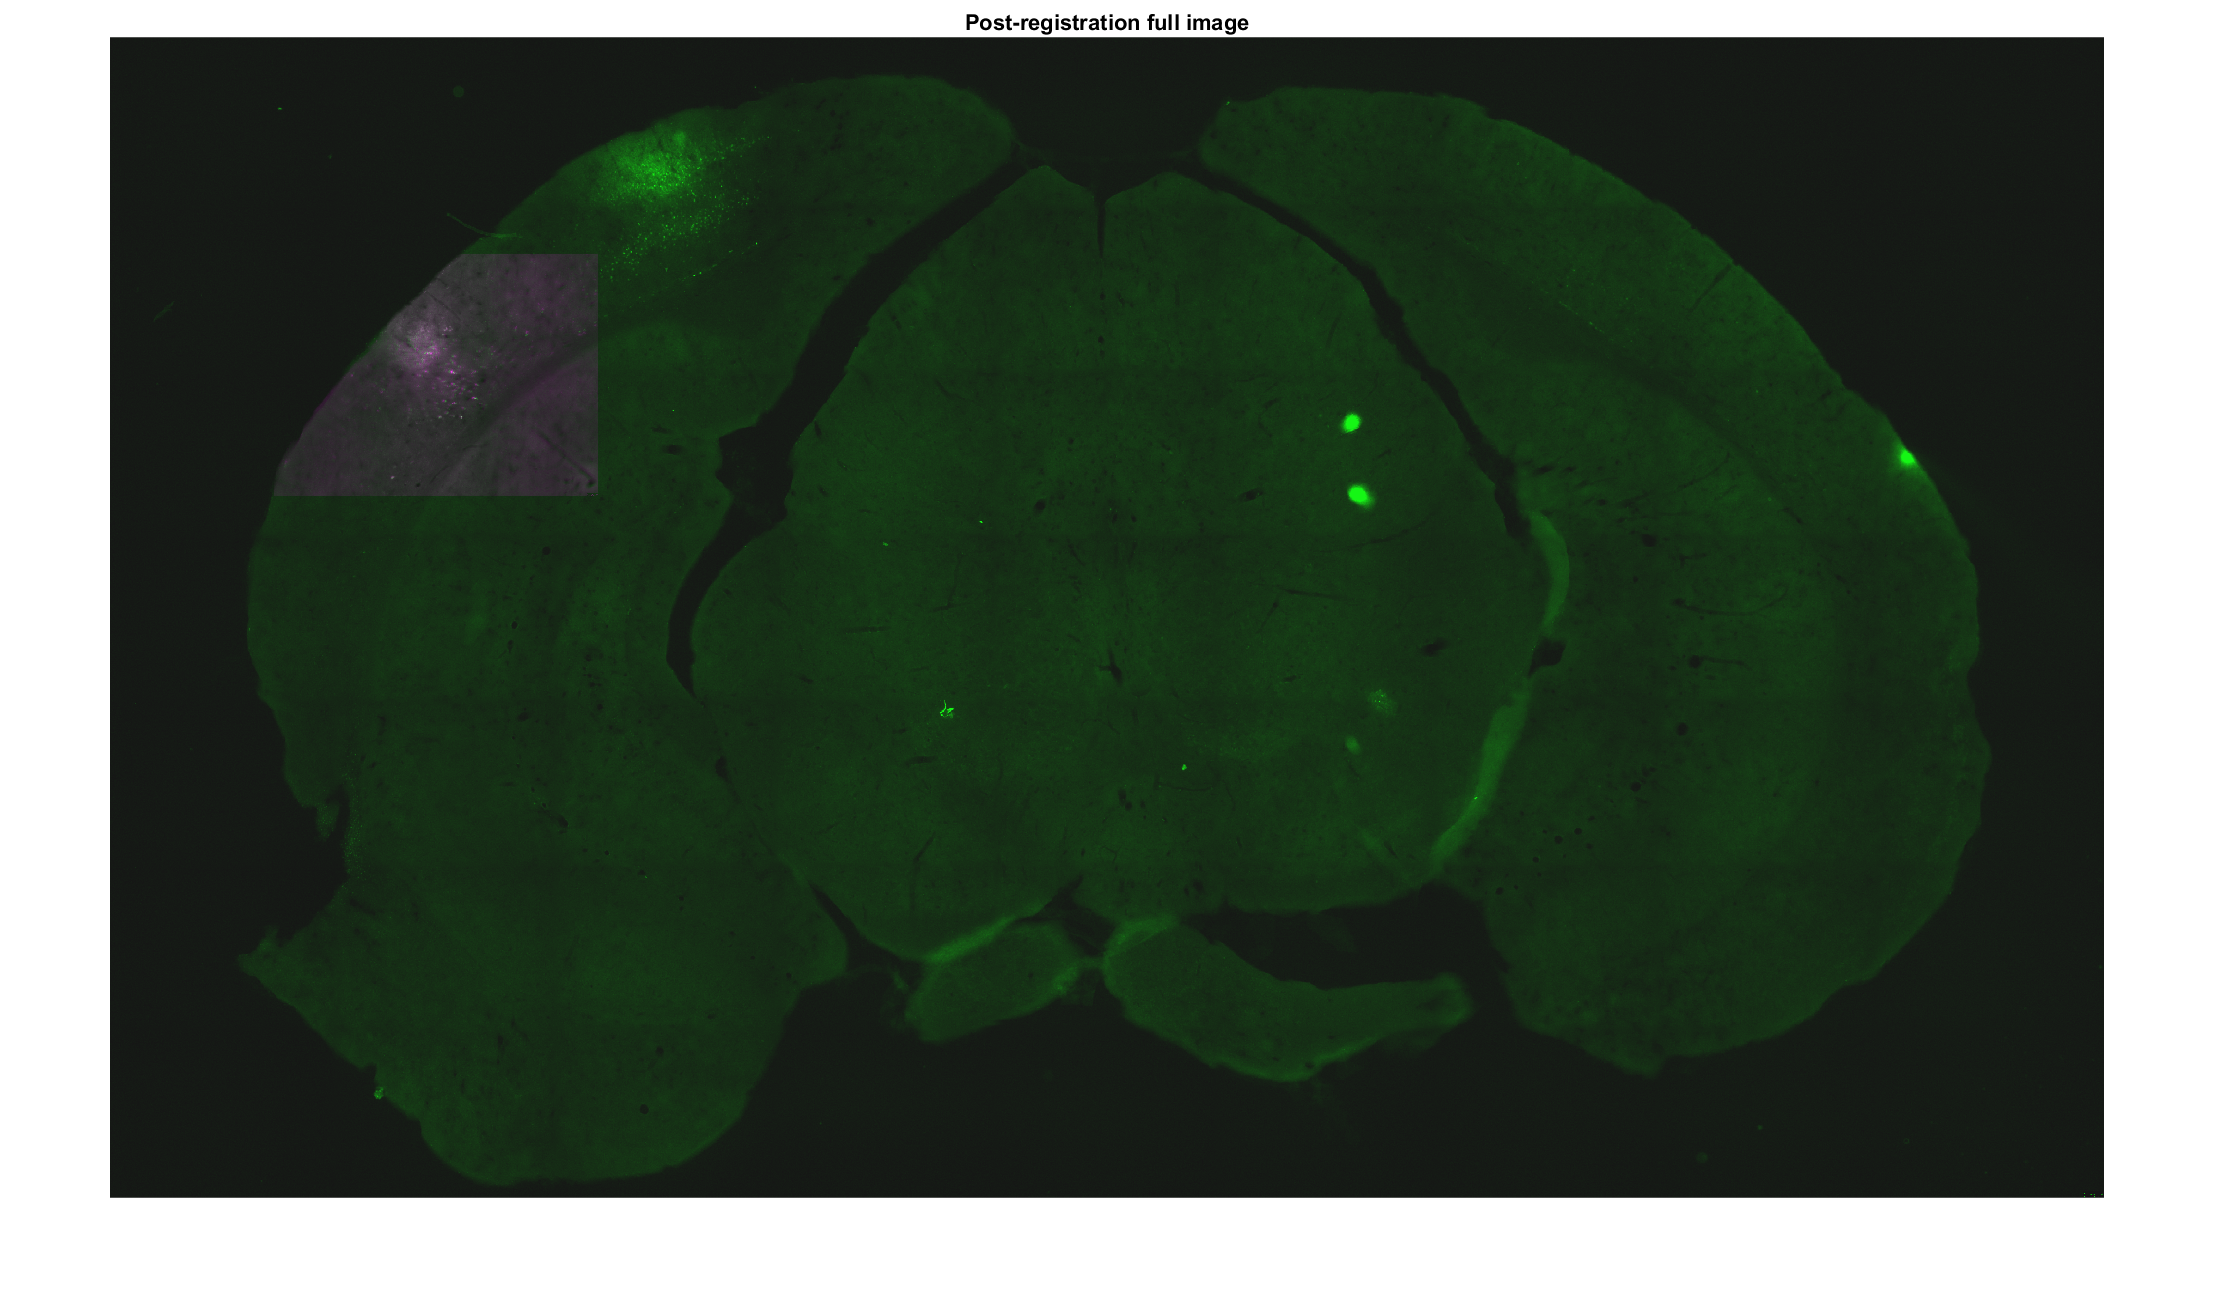

    title('Post-registration full image')

## Save images to 8-bit tiff

    final_low=uint8(im_low_sc);
    final_high=uint8(im_high_embed);

    imwrite(final_low,[im_dir filesep output_filename_low]);
    imwrite(final_high,[im_dir filesep output_filename_high]);